# Ejercicio 8.5

**Jose Antonio Lorencio Abril**

Primero introducimos los datos:

ano = 0:9;
pib = [950, 827, 817, 906, 986, 1113, 1170, 1132, 1222, 1330];

Definimos la función de recursión:

syms b;
syms k;
syms G;

f = @(x1, x2) G - b*k*x2 + b*(1+k)*x1;

Y ahora utilizamos los datos para estimar los parámetros:

len = length(pib);
pini1 = pib(1:len-2)';
pini2 = pib(2:len-1)';
pfin = pib(3:len)';

coef = polyfitn([pini1, pini2], pfin, {'constant', 'x', 'y'})

coef = struct with fields:
      ModelTerms: [3×2 double]
    Coefficients: [130.6198 -0.3145 1.2377]
    ParameterVar: [2.9687e+04 0.1070 0.0802]
    ParameterStd: [172.2996 0.3271 0.2832]
             DoF: 5
               p: [0.4826 0.3804 0.0072]
              R2: 0.9027
      AdjustedR2: 0.8637
            RMSE: 49.6566
        VarNames: {'x'  'y'}


Por lo que obtenemos $G=130.6198$, $b\cdot k = 0.3145$ y $b\cdot(1+k)=1.2377$. Resolvemos este sistema:

[bb,kk] = solve([b*k==0.3145, b*(1+k) == 1.2377], [b,k])

$$bb = \frac{577}{625}$$

$$kk = \frac{3145}{9232}$$

GG = 130.6198

GG = 130.6198

Ya tenemos todos los valores, y resolvemos la ecuación en diferencias usando el solve_rec:

syms n;

F(n) = solve_rec([bb*kk, -bb*(1+kk), 1], GG, [950, 827], n)

$$F(n) = \begin{array}{l} \frac{2414691143432639937585375\,{\left(-1\right)}^{n}\,2^{6-5\,n}\,\sigma_{1}\,\sqrt{27390129}\,{\left(-\sqrt{27390129}-12377\right)}^{n-1}}{63614775874172293147000832}-\frac{2414691143432639937585375\,{\left(-1\right)}^{n}\,2^{5-5\,n}\,\sigma_{1}\,\sqrt{27390129}\,{\left(\sqrt{27390129}-12377\right)}^{n-1}}{31807387937086146573500416}-\frac{461150294974136305625\,2^{1-5\,n}\,\left({\sigma_{2}}^{2\,n}+629000^{2\,n}\right)}{1306430920030420992\,5^{\frac{9\,n}{2}}\,629^{n/2}\,{\sigma_{2}}^{n}}+\frac{1436179889177755625}{844424930131968}\\ \mathrm{where}\\ \sigma_{1}=5^{4-4\,n}\\ \sigma_{2}=12377\,\sqrt{3145}-\sqrt{86141955705} \end{array}$$

Por último, comprobamos gráficamente el ajuste:

y = F(ano)

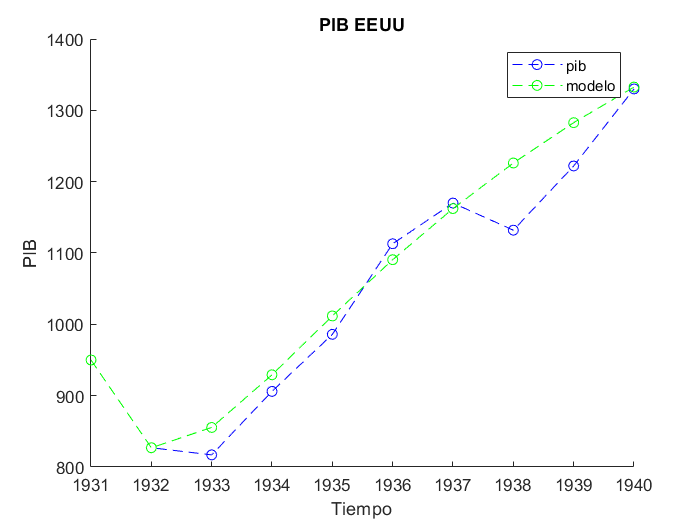


figure(1)
hold on
plot(ano+1931, pib, 'o--b')
plot(ano+1931, y, 'o--g')
legend('pib', 'modelo')
title('PIB EEUU')
xlabel('Tiempo')
ylabel('PIB')
hold off

Como vemos, el ajuste es decente, aunque tras el gran descenso en 1938 se desvía. Lo cual parece razonable.